#     Lab 7

## 1. tea.wav FFT

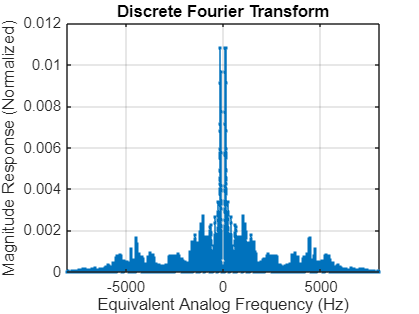

[tea, Ftea] = audioread("tea.wav");
%sound(tea, Ftea);
FT(tea, Ftea);

## 3. Filter

number_of_samples = 21334

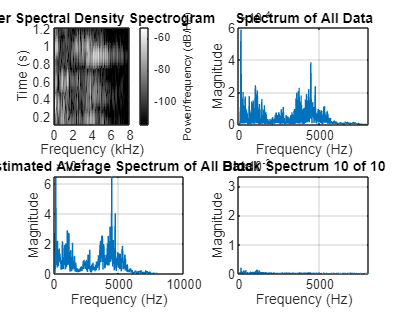

teaFiltered = digital_filter("tea.wav", "tea19hanningfiltered.wav");

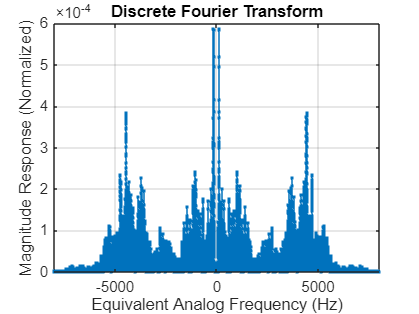

%sound(teaFiltered, Ftea);
figure;
FT(teaFiltered, Ftea);

## Filter Time Plots

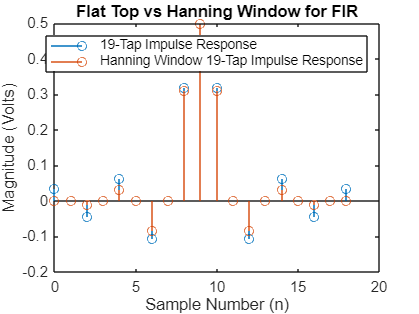

h7 = [-0.106, 0.000, 0.318, 0.500, 0.318, 0.000, -0.106];
h = [ 0.0354, -0.0000, -0.0455, 0.0000, 0.0637, -0.0000, -0.1061, 0.0000, 0.3183, 0.5000, 0.3183, 0.0000,-0.1061,-0.0000, 0.0637, 0.0000,-0.0455,-0.0000, 0.0354];
hanning = [0.0245, 0.955, 0.2061, 0.3455, 0.5000, 0.6545, 0.7939, 0.9045, 0.9755, 1.000, 0.9755, 0.9045, 0.7939, 0.6545, 0.5000, 0.3455, 0.2061, 0.0955, 0.0245];

hfiltered = h .* hanning;
n = linspace(0, 18, 19);
figure;
stem(n, h);
hold on;
stem(n, hfiltered);
legend("19-Tap Impulse Response", "Hanning Window 19-Tap Impulse Response")
title("Flat Top vs Hanning Window for FIR")
xlabel("Sample Number (n)")
ylabel("Magnitude (Volts)")

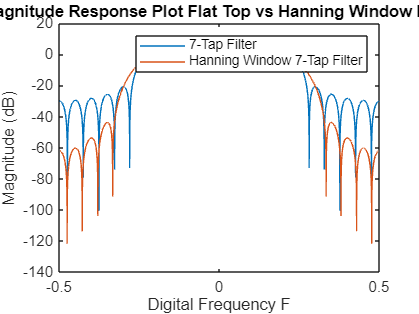


F = linspace (0, 0.5, 10000);
HDTFT = linspace (0, 0, 10000);
for m = 0:18
    HDTFT = HDTFT + h(m+1)*exp(-j*2*pi*F*(m)); 
end
HFiltDTFT = linspace (0, 0, 10000);
for m = 0:18
    HFiltDTFT = HFiltDTFT + hfiltered(m+1)*exp(-j*2*pi*F*(m)); 
end

figure;
plot(F, 20*log10(abs(HDTFT)));
hold on;
plot(F, 20*log10(abs(HFiltDTFT)));
legend("7-Tap Filter", "Hanning Window 7-Tap Filter")
title("Magnitude Response Plot Flat Top vs Hanning Window Filter")
xlabel("Digital Frequency F")
ylabel("Magnitude (dB)")

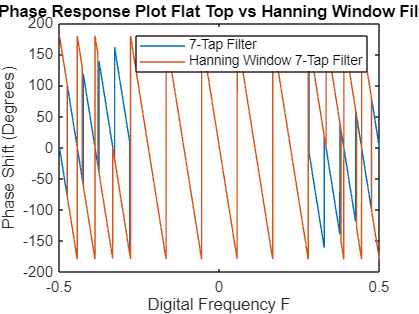

figure;
plot(F, 180*(angle(HDTFT))/pi);
hold on;
plot(F, 180*(angle(HFiltDTFT))/pi);
legend("7-Tap Filter", "Hanning Window 7-Tap Filter")
title("Phase Response Plot Flat Top vs Hanning Window Filter")
xlabel("Digital Frequency F")
ylabel("Phase Shift (Degrees)")

## Plots

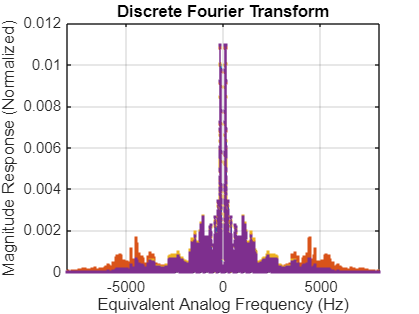

[Fctea,Flin] = FT(tea, Ftea);
[FcteaFilteredNorm,Flin] = FT(teaFilteredNorm, Ftea);
[FcteaHaningFiltered,Flin] = FT(teaHanningFiltered, Ftea);

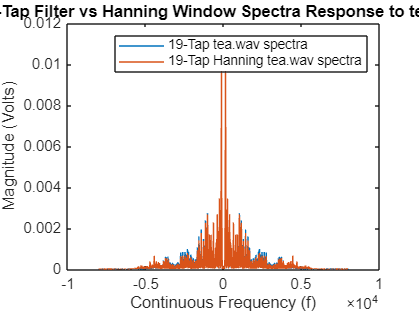


figure;
newplot;
plot(Flin, abs(FcteaFilteredNorm));
hold on;
plot(Flin, abs(FcteaHaningFiltered));
legend("19-Tap tea.wav spectra", "19-Tap Hanning tea.wav spectra")
title("19-Tap Filter vs Hanning Window Spectra Response to tea.wav")
xlabel("Continuous Frequency (f)")
ylabel("Magnitude (Volts)")

## Sounds

sound(tea, Ftea);
%sound(teaFilteredNorm, Ftea);
%sound(teaHanningFiltered, Ftea);